# Linear Control Design II - Group Work Problem Module 6 

## Description

Figure 1 shows an aircraft in lateral motion where the movements are yaw (rotation around the vertical axis) and roll (rotation around the longitudinal axis). The lateral motion of an aircraft takes primarily place in the horizontal plane. 

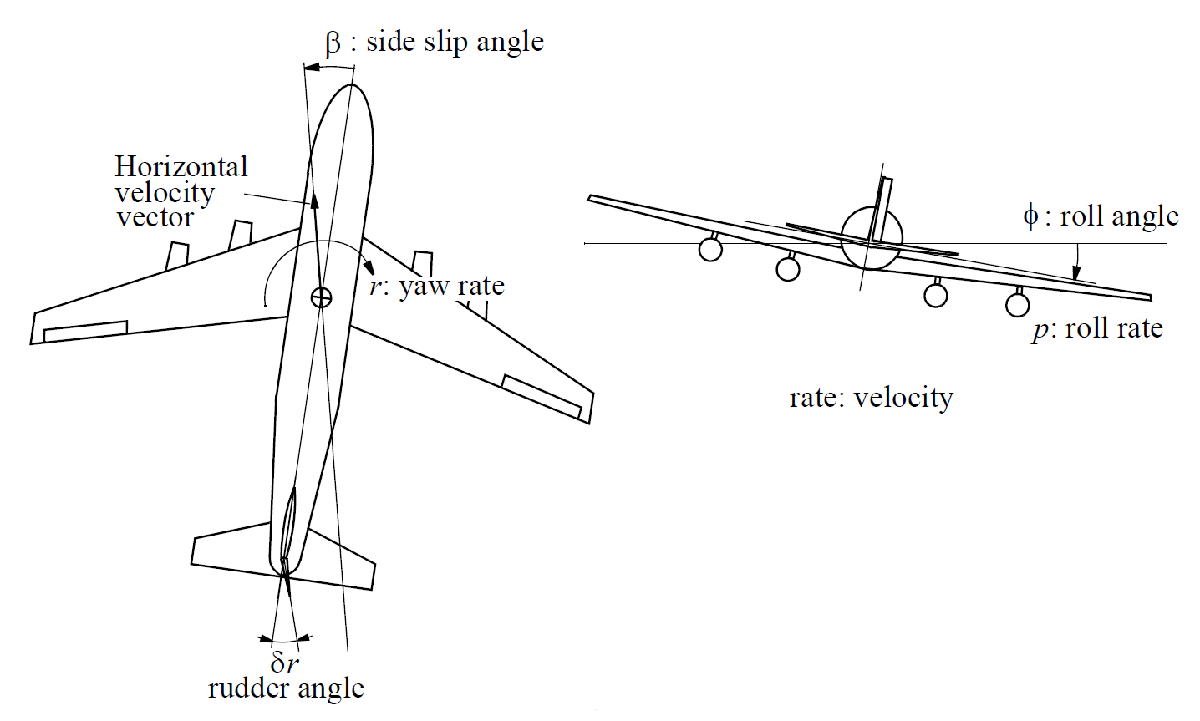  

			Figure 1: Lateral dynamics of a Boeing 747

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:

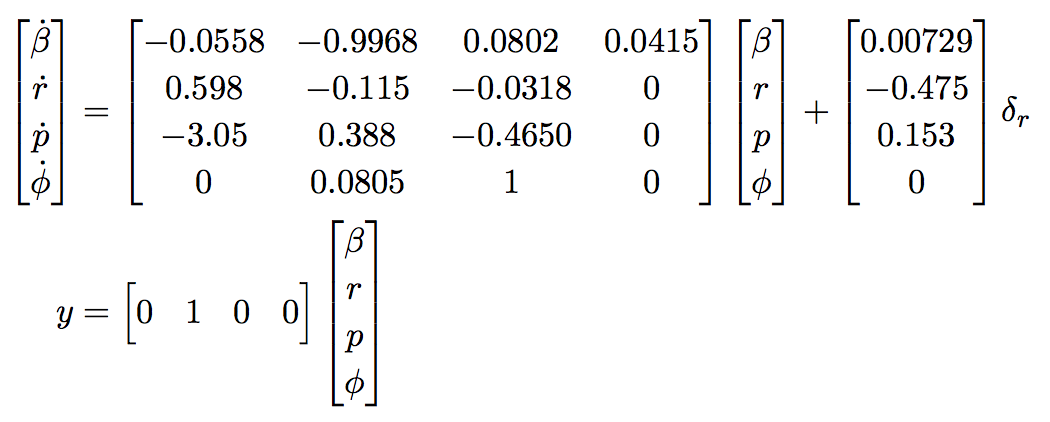

where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), and $\delta_r$ is the rudder deflection (rad). 

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =       -0.0558      -0.9968       0.0802       0.0415
        0.598       -0.115      -0.0318            0
        -3.05        0.388       -0.465            0
            0       0.0805            1            0


B = [0.00729; -0.475; 0.153; 0]

B =       0.00729
       -0.475
        0.153
            0


C = [0 1 0 0]

C =      0     1     0     0


D = 0;

This assignment guides you through the analysis of the aircraft’s lateral dynamics in terms of natural modes and system responses to non-zero initial conditions and external inputs. 

**Problem 1** Calculate the eigenvalues of the system dynamical matrix A, and based on those identify, if relevant, the time constants, natural frequencies and damping ratios. 

% Your solution goes here:

[M, Lam] = eig(A)

M =       0.19937 -    0.10627i      0.19937 +    0.10627i    -0.017178 +          0i    0.0067218 +          0i
    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
    -0.016547 +    0.66677i    -0.016547 -    0.66677i     -0.48953 +          0i    -0.010525 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i


Lam =     -0.032935 +    0.94665i            0 +          0i            0 +          0i            0 +          0i
            0 +          0i    -0.032935 -    0.94665i            0 +          0i            0 +          0i
            0 +          0i            0 +          0i     -0.56265 +          0i            0 +          0i
            0 +          0i            0 +          0i            0 +          0i    -0.007278 +          0i


tau = 1./abs(diag(Lam));

omega_n = abs(diag(Lam));
zeta = -real(diag(Lam))./omega_n;
freq_n = 2*pi*omega_n;
Damped = [zeta omega_n tau]

Damped =       0.03477      0.94723       1.0557
      0.03477      0.94723       1.0557
            1      0.56265       1.7773
            1     0.007278        137.4


damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -3.29e-02 + 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -3.29e-02 - 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -5.63e-01                 1.00e+00       5.63e-01          1.78e+00    
 -7.28e-03                 1.00e+00       7.28e-03          1.37e+02    


**Problem 2** Based on the calculated eigenvalues determine the natural modes (also known as eigenmodes) of the system and plot their temporal evolution as time goes to infinitiy.

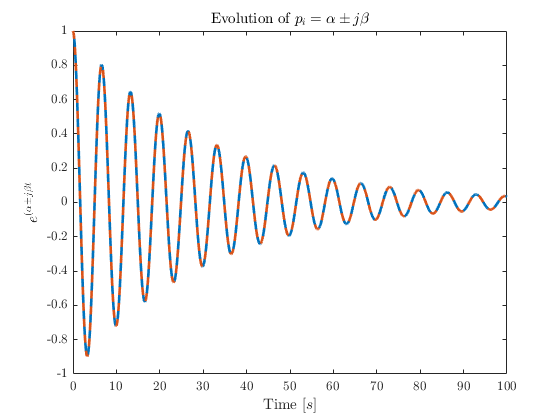

% Your solution goes here:
t1 = 0:0.1:100;
e1 = exp(Lam(1,1)*t1);
e2 = exp(Lam(2,2)*t1);
t2 = 0:0.01:10;
e3 = exp(Lam(3,3)*t2);
t3 = 0:1:1000;
e4 = exp(Lam(4,4)*t3);

figure
plot(t1,real(e1),'-', 'LineWidth',2)   
hold on
plot(t1,real(e2),'--','LineWidth',2)
title('Evolution of  $p_i=\alpha\pm j\beta$', 'interpreter','latex')
ylabel('$e^{(\alpha\pm j\beta t}$')
xlabel('Time $[s]$')

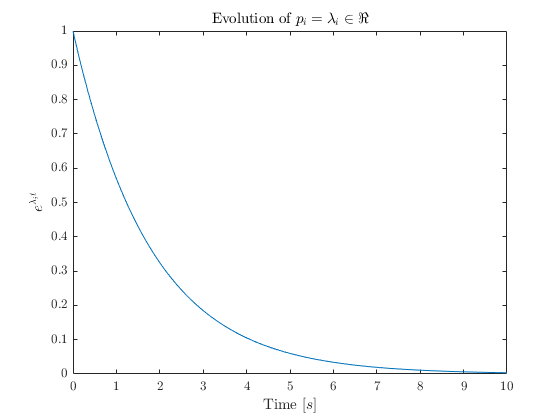

figure
plot(t2,e3)
title('Evolution of  $p_i = \lambda_i\in\Re$')
ylabel('$e^{\lambda_i t}$')
xlabel('Time $[s]$')

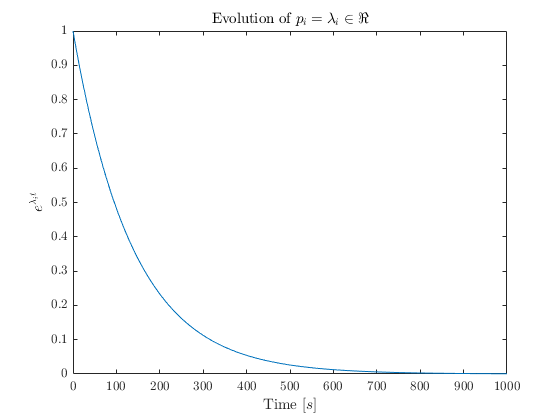

figure
plot(t3,e4)
title('Evolution of  $p_i = \lambda_i\in\Re$')
ylabel('$e^{\lambda_i t}$')
xlabel('Time $[s]$')

The eigenstructure of the lateral dynamics is usually represented by two real eigenvalues and one pair of complex conjugate eigenvalues. The three lateral modes are referred to as ***roll subsidence***, ***spiral*** and ***dutch roll***. 

- The **roll subsidence** **mode** is non-oscillatory and is usually decoupled from the spiral mode and from the dutch roll modes. In rolling motion the wing experiences a component of velocity normal to the wing resulting in a small increase in the angle of attack on the down- going wing and a small decrease on the up-going wing thus, generating a lift difference over the wing span. Moreover, the lift difference gives rise to a restoring roll moment represented by the roll subsidence mode. 

- The **spiral mode** is usually slow non-oscillatory and involves complex coupled motion in roll, yaw and side-slip angle. The spiral mode is usually excited by a disturbance in side-slip which is typically followed by a disturbance in roll. The side-slip angle generates a force on the tail fin, which in turn generates a yawing moment in the direction of the side-slip angle. The yawing motion generates increased differential lift across the wing span inducing increased roll moment and thereby, aggravates the situation. 

- The** dutch roll mode** is a damped oscillation and the motion is a complex interaction between the three lateral degrees of freedom. The dutch roll mode makes the wing tip move in an elliptic pattern seen from the side parallel to the wing. 

**Problem 3** Based on the found eigenvalues and the aforementioned modes, associate the eigenvalues to the corresponding mode of the lateral dynamics. 	

% Your solution goes here:




**Problem 4** Compute the modal matrix $\mathbf{M}_{lat}$of the system and discuss which natural modes contributes most and least to the dynamics of the state variables $\beta, r, p, \varphi$ (Make sure that your modal matrix has real elements)	

% Your solution goes here:
M

M =       0.19937 -    0.10627i      0.19937 +    0.10627i    -0.017178 +          0i    0.0067218 +          0i
    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
    -0.016547 +    0.66677i    -0.016547 -    0.66677i     -0.48953 +          0i    -0.010525 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i


M_real=[abs(M(:,1)) rad2deg(angle(M(:,1))) real(M(:,3:end))]

M_real =       0.22593      -28.059    -0.017178    0.0067218
       0.1544      -120.33    -0.011828     0.040422
      0.66697       91.422     -0.48953    -0.010525
      0.69301            0      0.87174       0.9991


**Problem 5** Determine the transfer function from rudder deflection $\delta_r$ to yaw rate r, and calculate the Bode’s diagram. Which of the aforementioned modes are visible in the magnitude response of the Bode’s diagram? 		

% Your solution goes here:
sys = ss(A,B,C,D);
[tf_num, tf_den] = ss2tf(A,B,C,D);
G=tf(tf_num,tf_den)


G =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



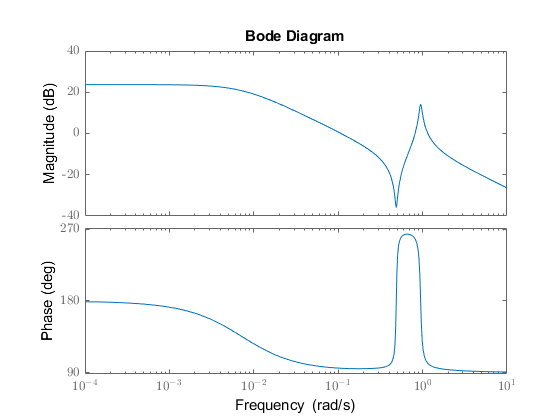

figure
bode(sys)

**Problem 6** Calculate the zero-state response for a step of 5 degrees in the rudder input. Analyse the response in connection with the modal analysis. 	

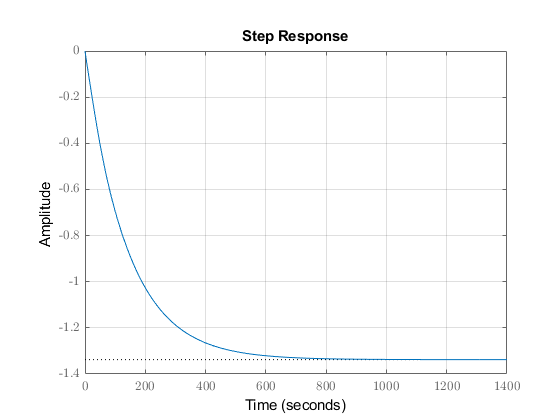

% Your solution goes here:

step_angle = 5*pi/180;
step(G*step_angle), grid

**Problem 7** Calculate the zero-input response for a side-slip initial angle $\beta_0 = 1$degree. Analyse the response in connection with the modal analysis. 	

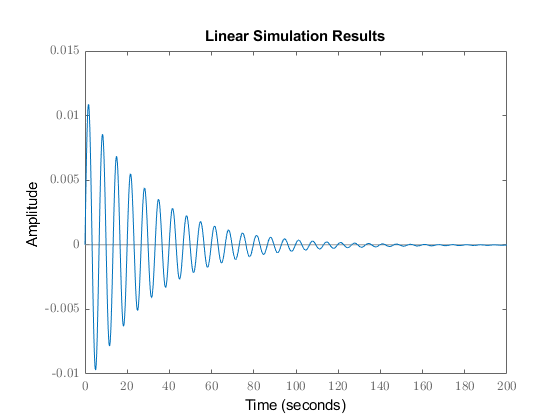

% Your solution goes here:
t = 0:0.1:200;
u = zeros(1,2001);
x_0 = [pi/180 0 0 0];
figure
lsim(sys,u,t,x_0)

**Problem 8** Calculate the zero-state response for the rudder deflection shown in the figure below and discuss the aircraft’s dynamical behaviour during these manoeuvres. 

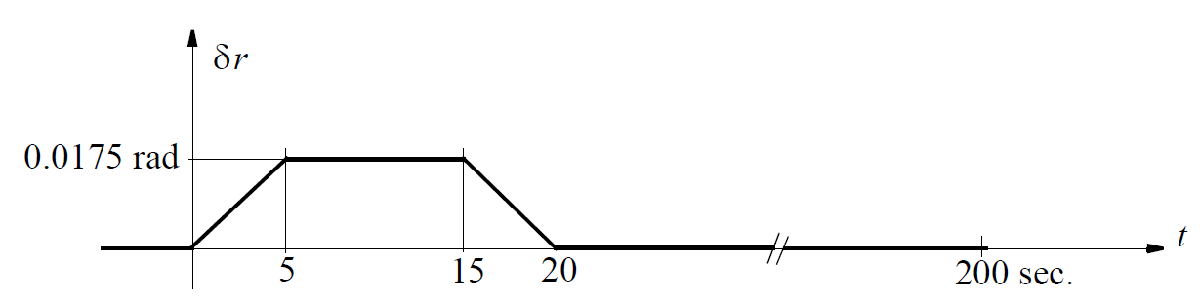

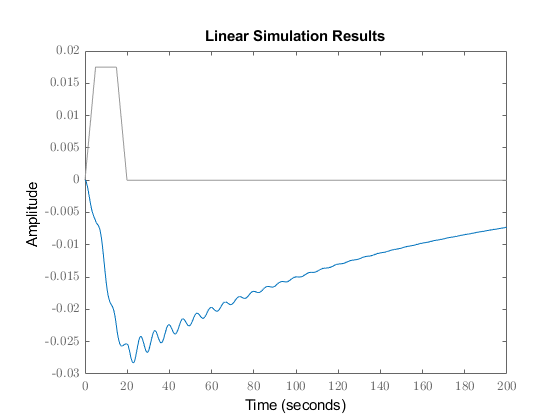

% Your solution goes here:
t = 0:0.1:199.9;
u00 = t(1,1:50) * 0.0175/5;
u05 = t(1,51:150) * 0 + 0.0175;
u15 = flip(u00,2);
u20 = t(1,201:2000) * 0;
x_0 = [0 0 0 0];
figure
lsim(sys,[u00 u05 u15 u20],t,x_0)